% set parameters
fs = 4000;
T = .5;
f = 1000;

%create time vector and the signal 
t = 0:1/fs:T-1/fs;
signal = sin(2*pi*f*t);

% get the frequency domain 
[fft_sig, freq_sig] = make_spectrum(signal, fs);

delta_f = 2

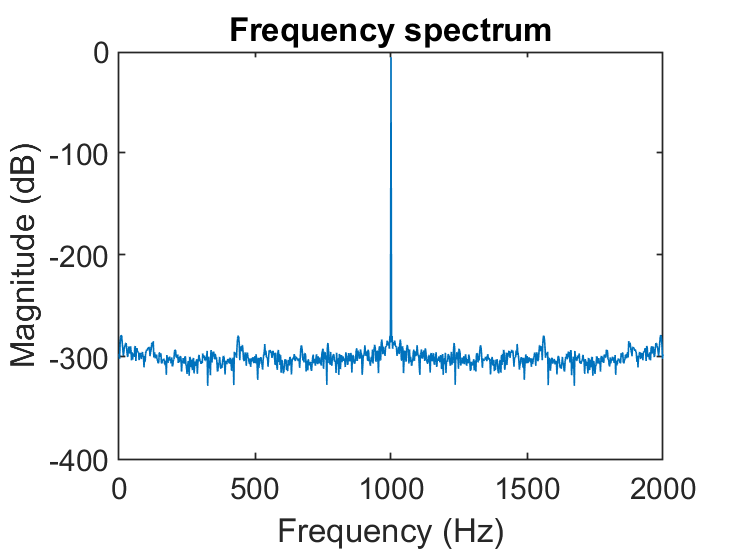

figure();
plot(freq_sig, 20*log10(abs(fft_sig)))
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
title("Frequency spectrum")
hold on

%Whistling
[whistle, fs] = audioread('whistle.m4a', [50001, 74000]);
[fft_whistle, freq_whistle] = make_spectrum(whistle, fs);

delta_f = 2

plot(freq_whistle, 20*log10(abs(fft_whistle)), 'r')

%Singing
[sing, fs] = audioread('Singing.m4a', [50001, 74000]);
[fft_sing, freq_sing] = make_spectrum(sing, fs);

delta_f = 2

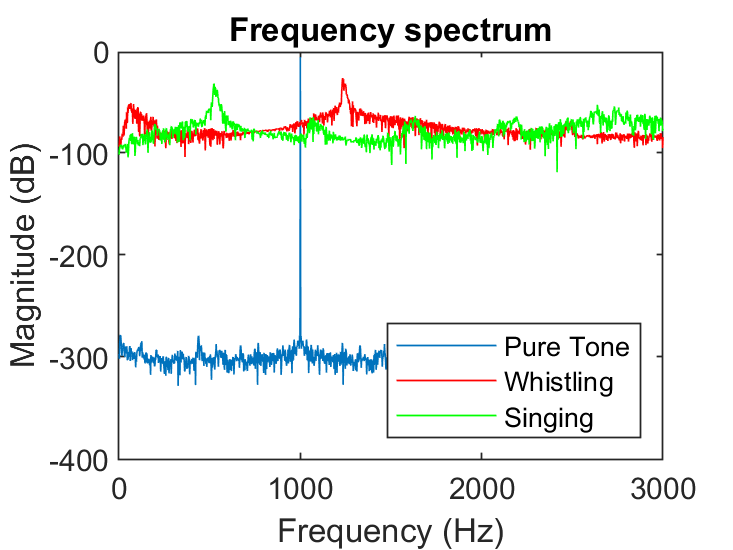

plot(freq_sing, 20*log10(abs(fft_sing)), 'g')

xlim([0 3000])


l = legend('Pure Tone', 'Whistling', 'Singing');
l.Location = 'southeast';
hold off

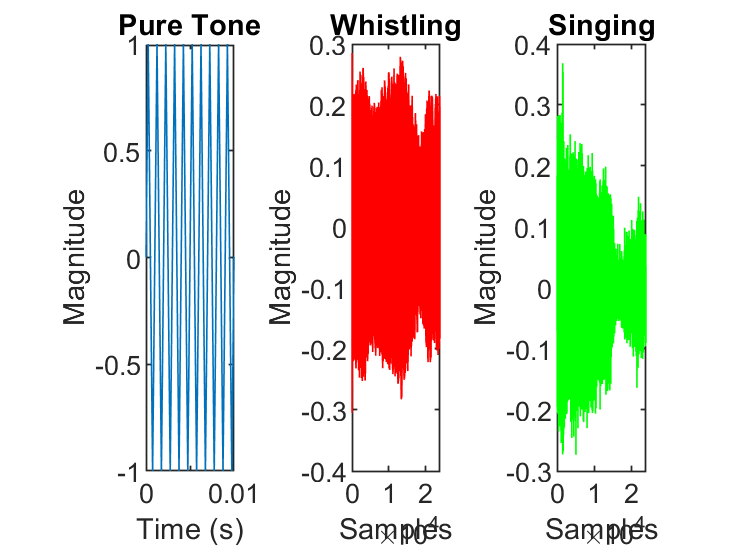


figure();
subplot(1,3,1)
plot(t, signal)
title("Pure Tone")
xlabel("Time (s)")
ylabel("Magnitude")
xlim([0 0.01])
hold on
subplot(1, 3, 2)
plot(whistle, 'r')
title("Whistling")
xlabel("Samples")
ylabel("Magnitude")
subplot(1,3,3)
plot(sing, 'g')
title("Singing")
xlabel("Samples")
ylabel("Magnitude")




%Impulse of iphone12 microphone
[impulse, fs_imp] = audioread('Impulse.m4a', [58001, 59000]);

sig_conv = conv(signal, impulse);

%sound(impulse,fs_imp)
figure();
%plot(sig_conv)

%sound(sig_conv, 4000)
[Y, freq] = make_spectrum(sig_conv, 4000);

delta_f = 1.3338

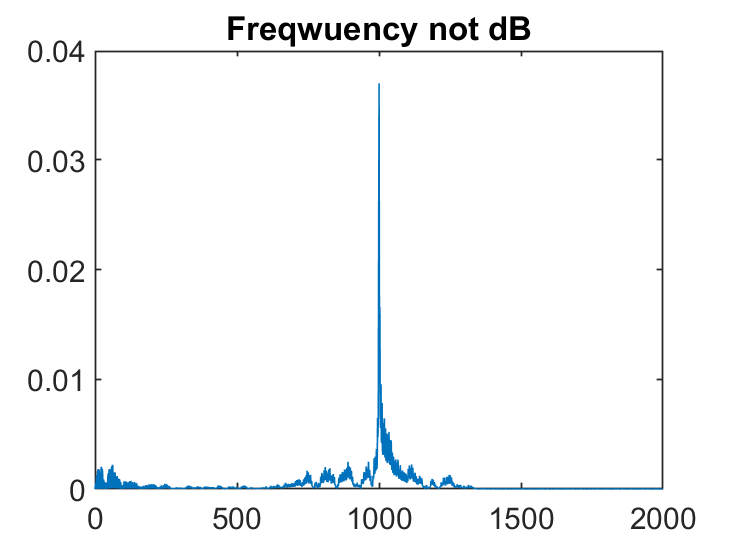

plot(freq, abs(Y))
title("Freqwuency not dB")

function [Y, freq] = make_spectrum(signal, fs)
    %take dft
    Y = fft(signal);
    
    Y = Y/(length(Y));
    
    %frequency step (should be 2)
    delta_f = fs/length(signal)
    freq = 0:delta_f:fs/2;

    Y = Y(1:length(freq));
    freq = freq(:);
    
end